#### Set Up

sample_values = modified_beta_inverse_cdf(rand(1,1e3),.55,.03);
my_cdf = @(p) modified_beta_cdf(p,.55,.03);
my_inverse_cdf = @(p) modified_beta_inverse_cdf(p,.55,.03);
bet_amounts = 90*rand(1,1e3)+10;

[classical_profit,palpha_final,pbeta_final] = classical_profit_from_sample(sample_values,bet_amounts);

[player_struct,mark_1_profit] = mark_1_gambling_system(sample_values,bet_amounts,2);

classical_focal_outcomes = zeros(1,1e3);
classical_compliment_outcomes = zeros(1,1e3);

mark_1_focal_outcomes = zeros(1,1e3);
mark_1_compliment_outcomes = zeros(1,1e3);

for index = 1:length(sample_values)

    % Classical
    if sample_values(index) >= palpha_final
        alpha = 100*palpha_final/(1-palpha_final);
        classical_focal_outcomes(index) = 100/alpha*bet_amounts(index); % Assume bet amount of 1
        classical_compliment_outcomes(index) = -1*bet_amounts(index); 
    elseif sample_values(index) <= pbeta_final
        beta = 100*pbeta_final/(1-pbeta_final);
        classical_compliment_outcomes(index) = beta/100*bet_amounts(index);
        classical_focal_outcomes(index) = -1*bet_amounts(index);
    end

    % Mark 1
    mark_1_focal_outcomes(index) = sum([player_struct(index).peer2peer_win_conditions].*[player_struct(index).peer2peer_pots]-player_struct(index).peer2peer_bet_amounts);
    mark_1_compliment_outcomes(index) = sum([~player_struct(index).peer2peer_win_conditions].*[player_struct(index).peer2peer_pots]-player_struct(index).peer2peer_bet_amounts);

    if ~isnan(player_struct(index).moneyline_win_condition)

        if player_struct(index).moneyline_win_condition
            alpha = 100*player_struct(index).moneyline_palpha/(1-player_struct(index).moneyline_palpha);
            mark_1_focal_outcomes(index) = mark_1_focal_outcomes(index) + 100/alpha*player_struct(index).moneyline_bet_amount;
            mark_1_compliment_outcomes(index) = mark_1_compliment_outcomes(index) - player_struct(index).moneyline_bet_amount;
        else
            beta = 100*player_struct(index).moneyline_pbeta/(1-player_struct(index).moneyline_pbeta);
            mark_1_focal_outcomes(index) = mark_1_focal_outcomes(index) - player_struct(index).moneyline_bet_amount;
            mark_1_compliment_outcomes(index) = mark_1_compliment_outcomes(index) + beta/100*player_struct(index).moneyline_bet_amount;
        end
    end
end

classical_profit

classical_profit = 1.1018e+03

-sum(classical_focal_outcomes)

ans = 1.1019e+03

-sum(classical_compliment_outcomes)

ans = 1.1044e+03


mark_1_profit

mark_1_profit = 1.2259e+03

-sum(mark_1_focal_outcomes)

ans = 1.2260e+03

-sum(mark_1_compliment_outcomes)

ans = 1.2263e+03

#### Mark 1 (Categories)

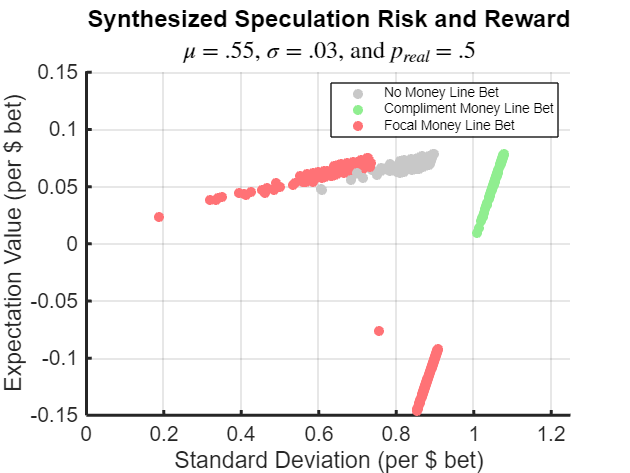

p_real = 1/2;

mark_1_real_expected_values = p_real*mark_1_focal_outcomes + (1-p_real).*mark_1_compliment_outcomes;


mark_1_real_variance_values = p_real*(mark_1_focal_outcomes-mark_1_real_expected_values).^2 + ...
                            (1-p_real)*(mark_1_compliment_outcomes-mark_1_real_expected_values).^2;

mark_1_real_stdev_values = sqrt(mark_1_real_variance_values);


figure
hold on
for index = 1:length(sample_values)

    if player_struct(index).moneyline_bet_amount == 0
       no_ml_bet = plot(mark_1_real_stdev_values(index)/bet_amounts(index),mark_1_real_expected_values(index)/bet_amounts(index),'LineStyle','none','Marker','.','Color',[200 200 200]/255,'MarkerSize',20);  
    end

    if player_struct(index).moneyline_win_condition == 0
       ml_comp_bet = plot(mark_1_real_stdev_values(index)/bet_amounts(index),mark_1_real_expected_values(index)/bet_amounts(index),'LineStyle','none','Marker','.','Color',[144 238 144]/255,'MarkerSize',20); 
    end

    if player_struct(index).moneyline_win_condition == 1
       ml_focal_bet = plot(mark_1_real_stdev_values(index)/bet_amounts(index),mark_1_real_expected_values(index)/bet_amounts(index),'LineStyle','none','Marker','.','Color',[255 114 118]/255,'MarkerSize',20); 
    end

end
xlabel(sprintf('Standard Deviation (per %s bet)','$'),'FontSize',16)
ylabel(sprintf('Expectation Value (per %s bet)','$'),'FontSize',16)
title('Synthesized Speculation Risk and Reward','FontSize',18)
subtitle('$\mu$ = .55, $\sigma$ = .03, and $p_{real}$ = .5','Interpreter','latex','FontSize',16)
legend([no_ml_bet,ml_comp_bet,ml_focal_bet],{'No Money Line Bet','Compliment Money Line Bet','Focal Money Line Bet'})

sexy_plot
ylim([-.15 .151])
xlim([0 1.25])
hold off

#### Mark 1 (Peer Bet on Compliment, Money Line Bet on Focal)

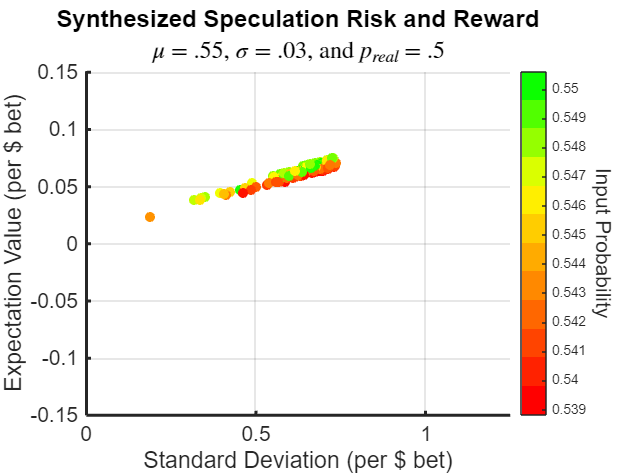

interval_min = inf;
interval_max = 0;
for index = 1:length(sample_values)
    if sum([player_struct(index).peer2peer_win_conditions]) == 0 && player_struct(index).moneyline_win_condition == 1 && sample_values(index) < my_inverse_cdf(.5) % Median
        interval_min = min(interval_min,sample_values(index));
        interval_max = max(interval_max,sample_values(index));
    end
end

figure
hold on
for index = 1:length(sample_values)
    if sum([player_struct(index).peer2peer_win_conditions]) == 0 && player_struct(index).moneyline_win_condition == 1 && sample_values(index) < my_inverse_cdf(.5) % Median
        prob_values_percentile = (sample_values(index)-interval_min)/(interval_max-interval_min);
        red_value = min(3-3*prob_values_percentile,1);
        green_value = min(3/2*prob_values_percentile,1);
        blue_value = 0;
        plot_color = [red_value,green_value,blue_value];
        plot(mark_1_real_stdev_values(index)/bet_amounts(index),mark_1_real_expected_values(index)/bet_amounts(index),'LineStyle','none','Marker','.','Color',plot_color,'MarkerSize',20)
    end
end
xlabel(sprintf('Standard Deviation (per %s bet)','$'),'FontSize',16)
ylabel(sprintf('Expectation Value (per %s bet)','$'),'FontSize',16)
title('Synthesized Speculation Risk and Reward','FontSize',18)
subtitle('$\mu$ = .55, $\sigma$ = .03, and $p_{real}$ = .5','Interpreter','latex','FontSize',16)


% Colorbar
the_colorbar = colorbar('Ticks',round(interval_min-.005,2):.001:round(interval_max+.005,2));
clim([interval_min-.0003 interval_max+.0003])
prob_values = interval_min:.001:interval_max;
red_values = min(3-3*(prob_values-interval_min)/(interval_max-interval_min),1)';
green_values = min(3/2*(prob_values-interval_min)/(interval_max-interval_min),1)';
blue_values = zeros(1,length(prob_values))';
colormap([red_values, green_values, blue_values])
ylabel(the_colorbar,'Input Probability','Rotation',270,'FontSize',14)

sexy_plot
ylim([-.15 .151])
xlim([0 1.25])
hold off